# 积分运算

## 不定积分

syms x
y = x^2

$$y = x^{2}$$

int(y, x) % Matlab不会自动添加 C 常数

$$ans = \frac{x^{3}}{3}$$

y = 1/x;
int(y,x) % 注意Matlab 没有为我们的log函数 加上绝对值，实际中是必要的

$$ans = \log\left(x\right)$$

syms x a
y = 1/sqrt(x^2 - a^2)

$$y = \frac{1}{\sqrt{x^{2}-a^{2}}}$$

int(y, x)

$$ans = \log\left(x+\sqrt{x^{2}-a^{2}}\right)$$

## 定积分

syms x a b
y = exp(x)

$$y = {\mathrm{e}}^{x}$$

int(y, x, a, b)

$$ans = {\mathrm{e}}^{b}-{\mathrm{e}}^{a}$$

syms x
I = (sin(x))^2/x^2

$$I = \frac{{\sin\left(x\right)}^{2}}{x^{2}}$$

int(I, x, 0, inf)

$$ans = \frac{\pi }{2}$$

## 数值积分

syms x
y = @(x) 1./exp(x).*log(x+2.*x.^2+sin(x))

y = 包含以下值的 function_handle :
    @(x)1./exp(x).*log(x+2.*x.^2+sin(x))


integral(y, 0, 4)

ans = 0.6014

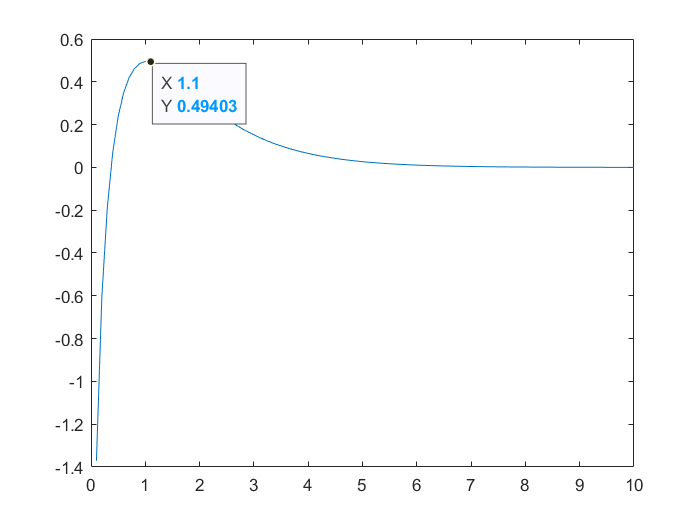

% 画出函数图像
xx = 0:1e-1:10;
yy = 1./exp(xx).*log(xx+2.*xx.^2+sin(xx));
plot(xx, yy, '-');
% 数据提示
ax = gca;
chart = ax.Children(1);
datatip(chart,1.1,0.494);